%% ===== Hydrophone Model Optimization (Based on Aquarian Audio AS-1 Data) =====
% Frequency data (Hz), phase (deg) and magnitude (Ohm)
freq = [1000, 2000, 5000, 10000, 15000, 20000, 25000, 30000, 35000, ...
        40000, 45000, 50000, 55000, 60000];
phase_deg = [-83, -88, -87, -88, -89, -89, -89.5, -90, -90.5, -91, ...
             -87, -89, -88, -88];
mag = [18500, 9000, 3500, 1600, 1000, 1000, 750, 500, 450, 400, ...
       380, 360, 320, 300];

% Convert measured data to complex impedance:
phase_rad = deg2rad(phase_deg);
Z_meas = mag .* exp(1j*phase_rad);
w_data = 2*pi*freq;

% Define the hydrophone equivalent model:
%   Z_hydro = Rs + j*w*Ls + 1/(1/Rp + j*w*Cp)
model_fun = @(p, w) p(1) + 1j*w*p(2) + 1./(1/p(3) + 1j*w*p(4));
% Cost function and optimization:
cost_fun = @(p) sum(abs(model_fun(p, w_data) - Z_meas).^2);
p0 = [100, 1e-3, 1000, 1e-9];  % Initial guess: [Rs, Ls, Rp, Cp]
opts = optimset('Display','iter');
p_opt = fminsearch(cost_fun, p0, opts);

 
 Iteration   Func-count         f(x)         Procedure
     0            1      4.51189e+08         
     1            5      4.50943e+08         initial simplex
     2            7      4.49849e+08         expand
     3            8      4.49849e+08         reflect
     4           10      4.49188e+08         expand
     5           12      4.48146e+08         expand
     6           14      4.46857e+08         expand
     7           15      4.46857e+08         reflect
     8           17      4.45163e+08         expand
     9           18      4.45163e+08         reflect
    10           20      4.44943e+08         reflect
    11           22      4.44585e+08         expand
    12           23      4.44585e+08         reflect
    13           24      4.44585e+08         reflect
    14           26      4.44585e+08         contract inside
    15           27      4.44585e+08         reflect
    16           29      4.44457e+08         reflect
    17           30      4.44457e+08   


% Extract optimized parameters:
Rs = p_opt(1);
Ls = p_opt(2);
Rp = p_opt(3);
Cp = p_opt(4);
fprintf('Optimized Hydrophone Parameters:\n');

Optimized Hydrophone Parameters:


fprintf('  Rs = %.2f ohm\n', Rs);

  Rs = 2.95 ohm


fprintf('  Ls = %.2e H\n', Ls);

  Ls = 1.67e-04 H


fprintf('  Rp = %.2f ohm\n', Rp);

  Rp = 155342.14 ohm


fprintf('  Cp = %.2e F\n', Cp);

  Cp = 8.62e-09 F


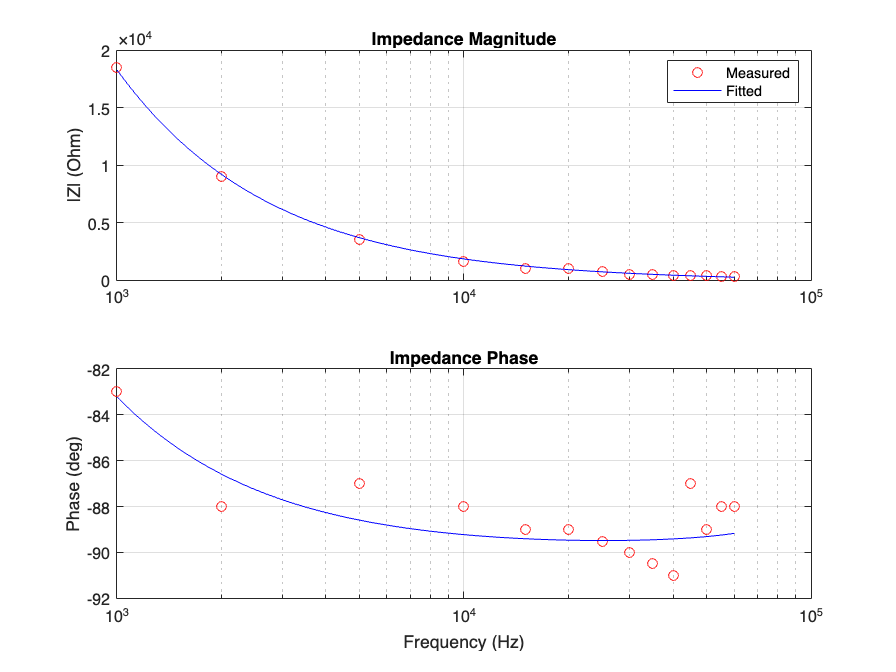


% (Optional) Plot measured vs. fitted impedance (magnitude and phase)
f_interp = logspace(log10(min(freq)), log10(max(freq)), 500);
w_interp = 2*pi*f_interp;
Z_fit = model_fun(p_opt, w_interp);
figure;
subplot(2,1,1);
semilogx(freq, abs(Z_meas), 'ro', f_interp, abs(Z_fit), 'b-');
ylabel('|Z| (Ohm)'); title('Impedance Magnitude'); legend('Measured','Fitted'); grid on;
subplot(2,1,2);
semilogx(freq, phase_deg, 'ro', f_interp, rad2deg(angle(Z_fit)), 'b-');
xlabel('Frequency (Hz)'); ylabel('Phase (deg)'); title('Impedance Phase'); grid on;


% Define the hydrophone impedance function (for simulation):
hydrophone_Z = @(w) Rs + 1j*w*Ls + 1./(1/Rp + 1j*w*Cp);

%% ===== Impedance Matching: Canceling the Hydrophone Reactance =====
% Fundamental frequency (set to 25 kHz here):
f0 = 25e3;   
w0 = 2*pi*f0;

% Evaluate hydrophone impedance at f0:
Z0 = hydrophone_Z(w0);  % Model: Rs + j*w0*Ls + 1/(1/Rp + j*w0*Cp)
fprintf('Hydrophone at 25 kHz: %.2f + j%.2f ohm\n', real(Z0), imag(Z0));

Hydrophone at 25 kHz: 6.46 + j-711.89 ohm



% Cancel the reactive part: want to add a series reactance j*X_cancel so that net imag = 0.
X_cancel = -imag(Z0);  
if X_cancel > 0
    % Hydrophone is capacitive (imaginary part negative); use series inductor:
    L_match = X_cancel / w0;
    fprintf('Using series inductor for matching: L_match = %.2e H\n', L_match);
    % Define series matching element impedance:
    Z_match = @(w) 1j * w * L_match;
else
    % If hydrophone were inductive, use series capacitor:
    C_match = 1/(w0 * abs(X_cancel));
    fprintf('Using series capacitor for matching: C_match = %.2e F\n', C_match);
    Z_match = @(w) -1./(1j*w*C_match);
end

Using series inductor for matching: L_match = 4.53e-03 H



% Define effective load impedance seen by the driver after matching:
% (Matching element in series with hydrophone)
Z_effective = @(w) Z_match(w) + hydrophone_Z(w);

% Assume a driver source resistance:
R_source = 1;  % Ohm (adjust as needed)

% Define the voltage–divider transfer functions:
H_raw = @(w) hydrophone_Z(w) ./ (R_source + hydrophone_Z(w));
H_matched = @(w) Z_effective(w) ./ (R_source + Z_effective(w));

%% ===== RC Low-Pass Filter Design (2nd-Order) =====
% Goal: attenuate harmonics (3f, 5f, 7f, etc.) of the square wave.
f_c = 40e3;  % Nominal cutoff frequency
R_filter = 1000;  % Resistor value in Ohm
C_filter = 1/(2*pi*f_c*R_filter);
fprintf('RC Filter Design: R_filter = %.2f ohm, C_filter = %.2e F\n', R_filter, C_filter);

RC Filter Design: R_filter = 1000.00 ohm, C_filter = 3.98e-09 F


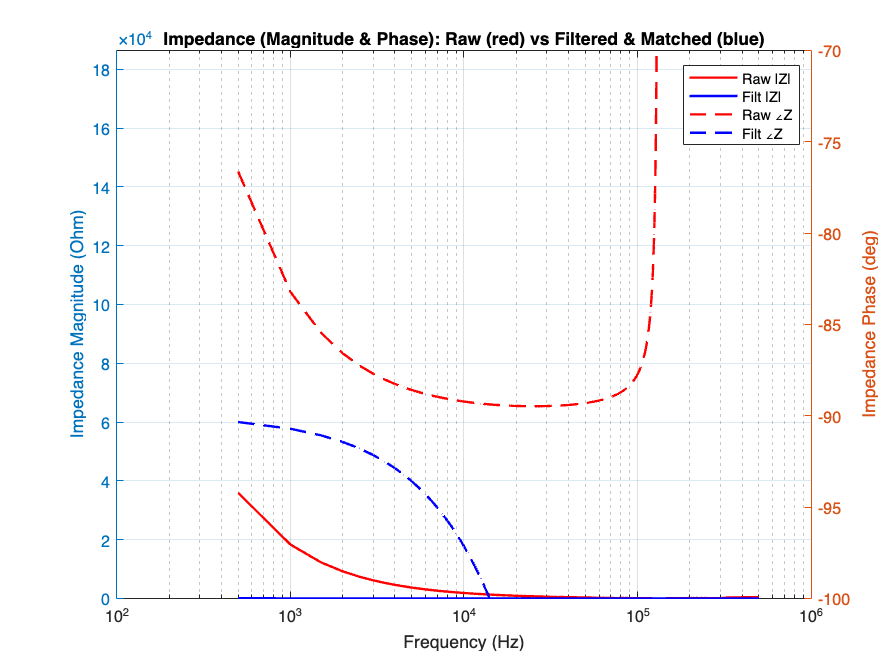


% Single RC low-pass transfer function:
H_RC = @(w) 1./(1 + 1j*w*R_filter*C_filter);
% Two cascaded stages (2nd order):
H_filter = @(w) (H_RC(w)).^2;

% Define overall filtered & matched transfer function:
% Here we “cascade” the RC filter with the matching network voltage divider.
H_total = @(w) H_filter(w) .* H_matched(w);

%% ===== Frequency Domain Simulation Setup =====
fs = 1e6;         % Simulation sampling frequency (Hz)
T  = 2e-3;        % Simulation total time (sec)
t  = 0:1/fs:T;    
N  = length(t);
if mod(N,2) ~= 0  % Force an even number of samples
    N = N - 1;
    t = t(1:N);
end

% Driver input: For a differential driver, use an equivalent single-ended square wave
% that swings from –12 V to +12 V (a 24 V differential swing).
Vin = 12 * square(2*pi*f0*t);  % Produces ±12 V

% Frequency vector for FFT (unique bins):
f_pos = (0:(N/2)) * fs/N;
w_pos = 2*pi*f_pos;

%% ===== Compute FFT Transfer Functions and Output Signals =====
% Evaluate the raw and matched transfer functions at f_pos:
H_raw_vals = H_raw(w_pos);
H_matched_vals = H_total(w_pos);

% Reconstruct full transfer function spectra (Hermitian symmetry):
H_raw_full = [H_raw_vals, conj(H_raw_vals(end-1:-1:2))];
H_matched_full = [H_matched_vals, conj(H_matched_vals(end-1:-1:2))];

% Compute FFT of input signal:
Vin_fft = fft(Vin);

% Compute output signals:
Vout_raw = real(ifft(Vin_fft .* H_raw_full));
Vout_matched = real(ifft(Vin_fft .* H_matched_full));

% Compute spectra (single-sided) for plotting:
Vraw_spec = abs(Vin_fft .* H_raw_full);
Vmatched_spec = abs(Vin_fft .* H_matched_full);

%% ===== Compute Effective Load Impedance from the Voltage Divider =====
% Given: H = Z_eff/(R_source + Z_eff)  =>  Z_eff = H*R_source/(1 - H)
% Use H_matched_vals (filtered & matched voltage divider) to “extract” Z_eff:
Z_eff_vals = H_matched_vals .* R_source ./ (1 - H_matched_vals + eps);

%% ===== Consolidated Impedance Plot (Magnitude & Phase) =====
figure;
yyaxis left
semilogx(f_pos, abs(hydrophone_Z(w_pos)), 'r-', 'LineWidth', 1.5); hold on;
semilogx(f_pos, abs(Z_eff_vals), 'b-', 'LineWidth', 1.5);
ylabel('Impedance Magnitude (Ohm)');
ylim([0, max([abs(hydrophone_Z(w_pos)), abs(Z_eff_vals)])*1.2]);

yyaxis right
semilogx(f_pos, rad2deg(angle(hydrophone_Z(w_pos))), 'r--', 'LineWidth', 1.5);
semilogx(f_pos, rad2deg(angle(Z_eff_vals)), 'b--', 'LineWidth', 1.5);
ylabel('Impedance Phase (deg)');
ylim([-100, -70]);

xlabel('Frequency (Hz)');
title('Impedance (Magnitude & Phase): Raw (red) vs Filtered & Matched (blue)');
legend({'Raw |Z|','Filt |Z|','Raw ∠Z','Filt ∠Z'}, 'Location', 'best');
grid on;

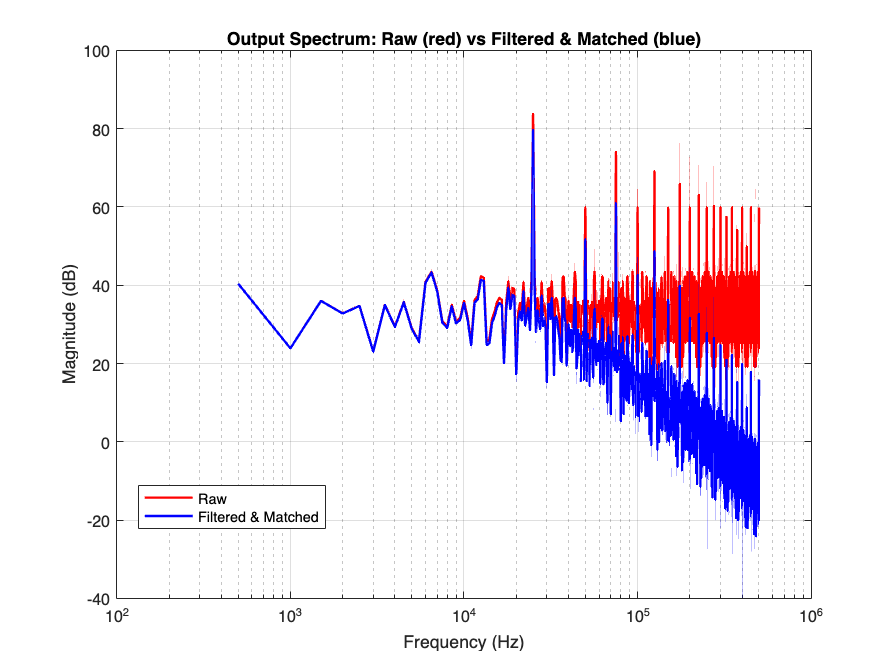


%% Consolidated Spectrum Plot
figure;
semilogx(f_pos, 20*log10(Vraw_spec(1:length(f_pos))+eps), 'r-', 'LineWidth', 1.5); hold on;
semilogx(f_pos, 20*log10(Vmatched_spec(1:length(f_pos))+eps), 'b-', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Output Spectrum: Raw (red) vs Filtered & Matched (blue)');
legend({'Raw','Filtered & Matched'},'Location','best');
grid on;

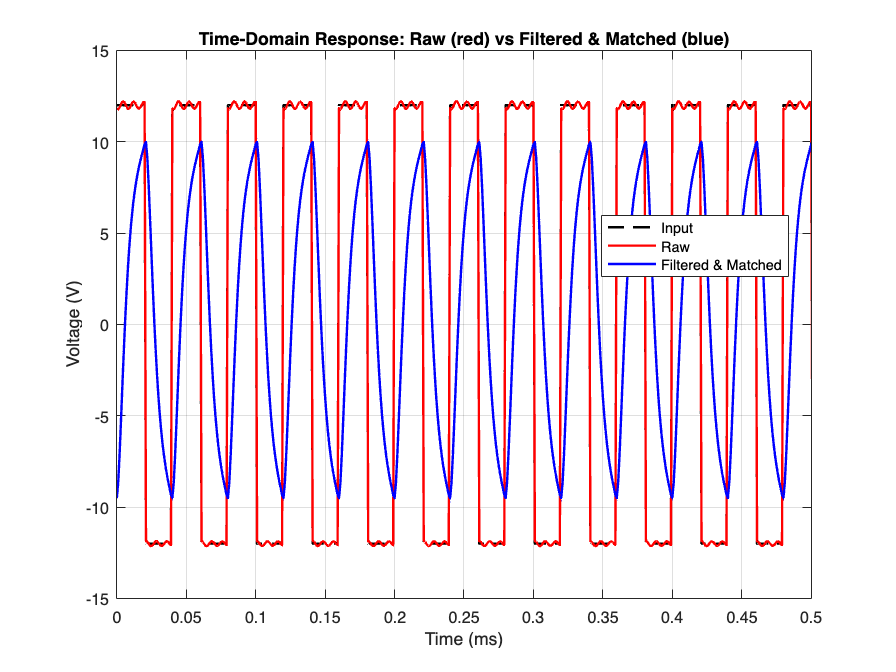


%% Consolidated Time-Domain Response Plot
figure;
plot(t*1e3, Vin, 'k--', 'LineWidth',1.5); hold on;
plot(t*1e3, Vout_raw, 'r-', 'LineWidth',1.5);
plot(t*1e3, Vout_matched, 'b-', 'LineWidth',1.5);
xlim([0 0.5])
xlabel('Time (ms)');
ylabel('Voltage (V)');
title('Time-Domain Response: Raw (red) vs Filtered & Matched (blue)');
legend({'Input','Raw','Filtered & Matched'},'Location','best');
grid on;

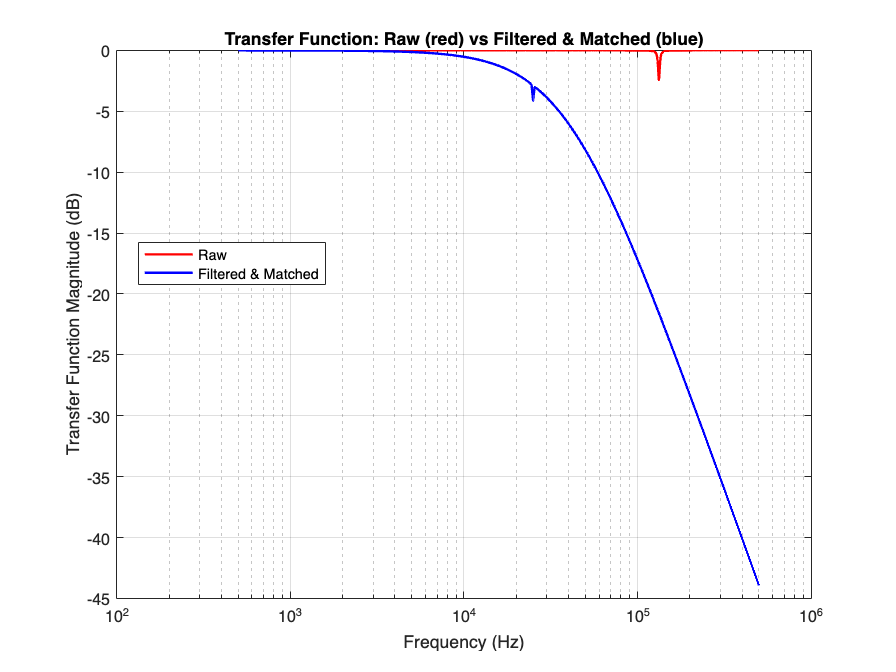


%% Consolidated Transfer Function Plot
figure;
semilogx(f_pos, 20*log10(abs(H_raw_vals)+eps), 'r-', 'LineWidth',1.5); hold on;
semilogx(f_pos, 20*log10(abs(H_matched_vals)+eps), 'b-', 'LineWidth',1.5);
xlabel('Frequency (Hz)');
ylabel('Transfer Function Magnitude (dB)');
title('Transfer Function: Raw (red) vs Filtered & Matched (blue)');
legend({'Raw','Filtered & Matched'},'Location','best');
grid on;